# First script

## Set params

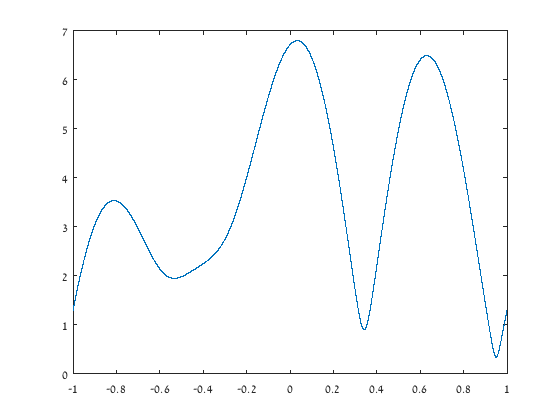

h = [2-0.4j 1.5+1.8j 1 1.2-1.3j 0.8+1.6j];
% h = [0.8 0.2];
n = 2^14;
figure;plot(linspace(-1,1,n),fftshift(abs(fft(h,n))));

%h = h / std(h);
L = length(h);
hCor = conv(h,h);  
repNum = 3;
m = 4;
tn = 2^11;
nvar = 1/20;
mBits = log2(m);
N = n*repNum/mBits;
trN = tn/mBits;

## TX path


% bits
bits = randi([0 1], 1, n);
trBits = randi([0 1], 1, tn);

symbs = EncryptorPath(bits, repNum);
trSymbs = symbMap(trBits);

channel_out = ChannelPass([trSymbs;symbs], h, nvar);
trChanSymbles = channel_out(1:trN);
chSymbs = channel_out(trN+1:trN+N);


## Turbo EQ loop

Equlizer = AdaEQ(L,0.001,1e-1); % set
hard = @(x) getHard(x);
% train equlizer
trEqOut = Equlizer.turboEqualize(trChanSymbles,trSymbs, 0.001);
err = calcError(trEqOut, trSymbs, hard);
disp(['train error turbo: ' num2str(err*100) '%']);

train error turbo: 5.8594%


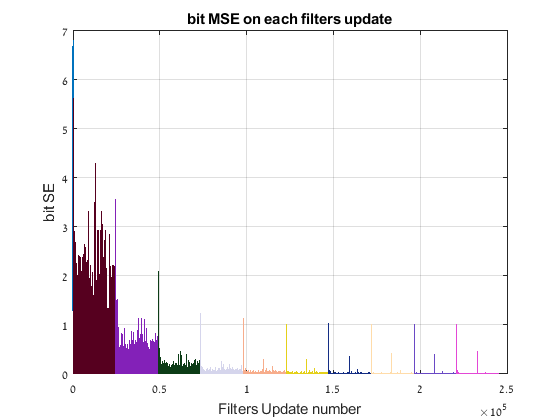

ieration 1: bit error rate: 0.26855%  MSE:0.34205


ieration 2: bit error rate: 0.0061035%  MSE:0.10832


ieration 3: bit error rate: 0%  MSE:0.033138


ieration 4: bit error rate: 0%  MSE:0.012805


ieration 5: bit error rate: 0%  MSE:0.006293


ieration 6: bit error rate: 0%  MSE:0.0036069


ieration 7: bit error rate: 0%  MSE:0.0023971


ieration 8: bit error rate: 0%  MSE:0.0018037


ieration 9: bit error rate: 0%  MSE:0.0015105


ieration 10: bit error rate: 0%  MSE:0.0013499



bias = 60;
maxiter = 10;

dn_ = zeros(size(chSymbs));
MSE = zeros(maxiter,1);
err = zeros(maxiter,1);
SE_bit = zeros((size(chSymbs,1)-bias)*maxiter,1);
% equlize data
figure(1);
xlabel("Filters Update number");
hold on;
ylabel("bit SE");
title("bit MSE on each filters update");
grid on;
xlim([0,2.5e5]);
for i = 1:maxiter
    if i == 1
        eqOut = Equlizer.normalEqualize_run(chSymbs, Equlizer.Mu);
    else
        eqOut = Equlizer.turboEqualize(chSymbs,dn_, Equlizer.Mu);
    end
    [dn_, Decoded] = DecoderPath(eqOut, repNum);
    
    err(i) = calcError(Decoded, bits);
    MSE(i) = mean(abs(eqOut - symbs).^2);
    
    SE_bit((size(chSymbs,1)*(i-1)+1):(size(chSymbs,1)*(i)-bias)) = abs(eqOut(1:(end-bias)) - symbs(1:(end-bias))).^2;
    plot((size(chSymbs,1)*(i-1)+1):(size(chSymbs,1)*(i)-bias),abs(eqOut(1:(end-bias)) - symbs(1:(end-bias))).^2,'color',rand(1,3));
    disp(['ieration ' num2str(i) ': bit error rate: ' num2str(err(i) * 100) '%  MSE:' num2str(MSE(i))]);
    fprintf('\n');
    %     if err == 0
%         break;
%     end
end

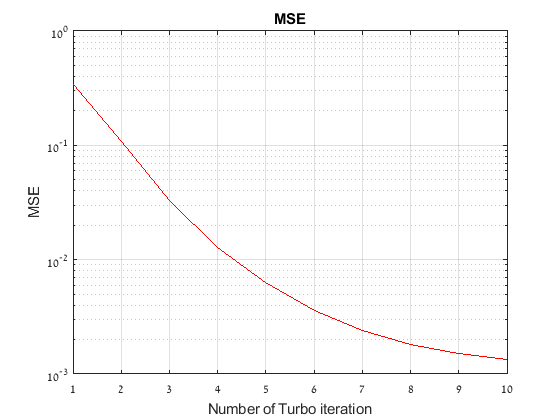

figure(2);
semilogy(MSE,'r');
hold on;
xlabel("Number of Turbo iteration");
ylabel("MSE");
title("MSE");
grid on;

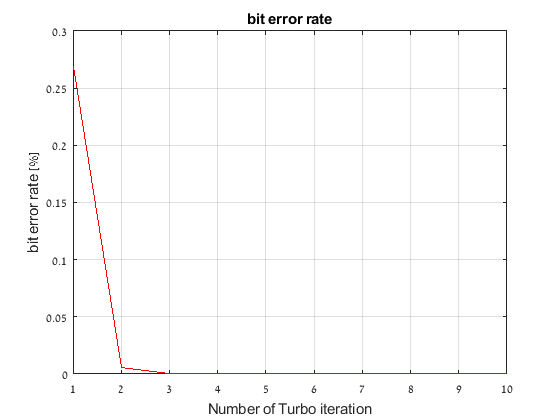


figure(3);
plot(err*100,'r')
hold on;
xlabel("Number of Turbo iteration");
ylabel("bit error rate [%]");
title("bit error rate");
grid on;

## Normal EQ loop

Equlizer = AdaEQ(L,0.001,1e-1); % set
hardFnc = @(x) x > 0;
% train equlizer
trEqOut = Equlizer.normalEqualize_train(trChanSymbles,trSymbs, 0.001);
err = calcError(trEqOut, trSymbs, hard);
disp(['train error normal: ' num2str(err*100) '%']);

train error normal: 5.8594%



% equlize data
maxiter = 10; 
MSE = zeros(maxiter,1);
err = zeros(maxiter,1);
for i = 1:maxiter
    eqOut = Equlizer.normalEqualize_run(chSymbs, Equlizer.Mu);

    [~, Decoded] = DecoderPath(eqOut, repNum);
    
    err(i) = calcError(Decoded, bits);
    MSE(i) = mean(abs(eqOut - symbs).^2);
    
    disp(['ieration ' num2str(i) ': bit error rate: ' num2str(err(i) * 100) '%  MSE:' num2str(MSE(i))]);
    fprintf('\n')
    %     if err == 0
%         break;
%     end
end

ieration 1: bit error rate: 0.26855%  MSE:0.34205


ieration 2: bit error rate: 0.16479%  MSE:0.32862


ieration 3: bit error rate: 0.16479%  MSE:0.32862


ieration 4: bit error rate: 0.16479%  MSE:0.32862


ieration 5: bit error rate: 0.16479%  MSE:0.32862


ieration 6: bit error rate: 0.16479%  MSE:0.32862


ieration 7: bit error rate: 0.16479%  MSE:0.32862


ieration 8: bit error rate: 0.16479%  MSE:0.32862


ieration 9: bit error rate: 0.16479%  MSE:0.32862


ieration 10: bit error rate: 0.16479%  MSE:0.32862


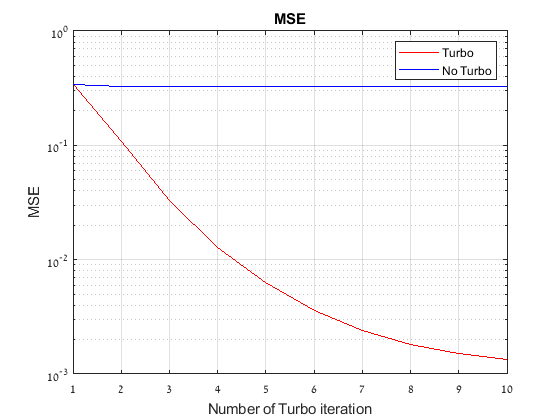

figure(2);
semilogy(MSE,'b');
legend("Turbo","No Turbo");

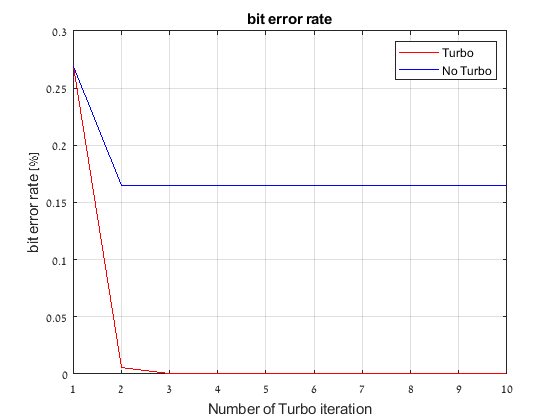

figure(3);
plot(err*100,'b');
legend("Turbo","No Turbo");